# Generic Omniwheel

Copyright 2018-2019 The MathWorks, Inc.

## Kinematic Model

This vehicle has an arbitrary number $N$ of omniwheels, positioned and oriented relative to the center of gravity (C.G.) of the vehicle.

With 3 or more independently actuated wheels, the vehicle has full motion control in all degrees of freedom. Exactly 3 wheels leads to unique solutions, and 4 or more wheels has multiple solutions.

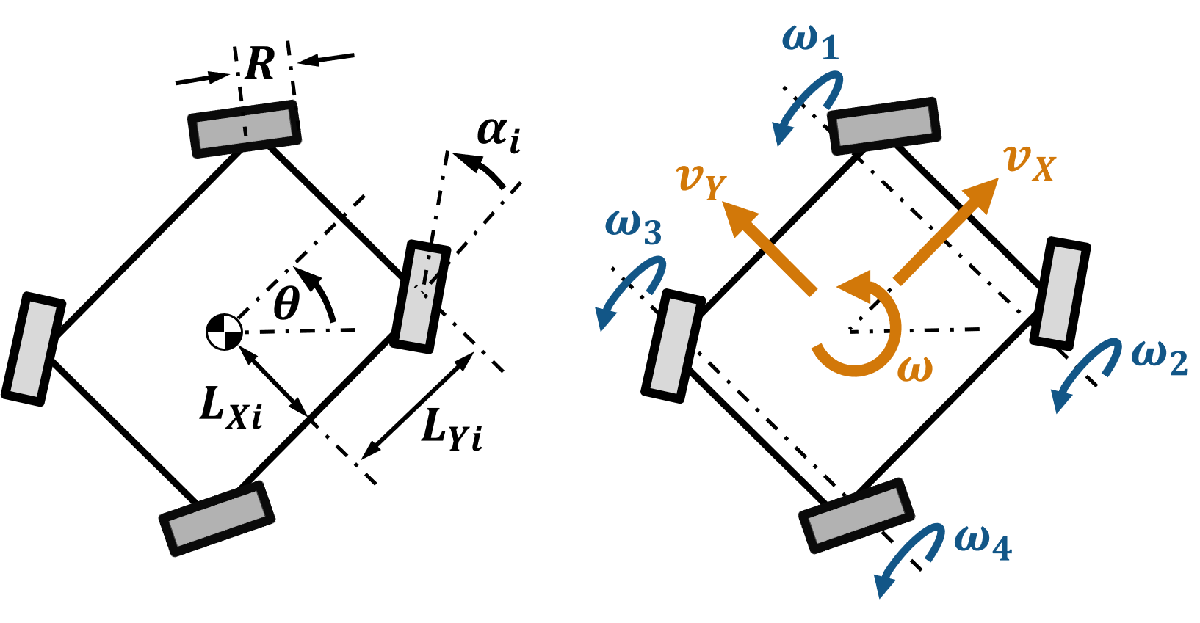

**Inputs:**

- Wheel speeds $\left\lbrack \omega_1 ;\omega_2 ;\ldotp \ldotp \ldotp ;\omega_N \right\rbrack$, in rad/s

**Outputs**

- Linear velocities$v_X$ and $v_Y$, in m/s

- Angular velocity $\omega$, in rad/s

**Forward Kinematics**

The forward kinematics can be expressed in matrix form as follows.


$$\begin{array}{l}
{\left[\begin{array}{c}
v_X \\
v_Y \\
\omega 
\end{array}\right]}=\frac{R}{N}\left\lbrack \begin{array}{cccc}
\cos \left(\alpha_1 \right) & \cos \left(\alpha_2 \right) & \ldotp \ldotp \ldotp  & \cos \left(\alpha_N \right)\\
\sin \left(\alpha_1 \right) & \sin \left(\alpha_2 \right) & \ldotp \ldotp \ldotp  & \sin \left(\alpha_N \right)\\
\frac{1}{D_1 } & \frac{1}{D_2 } & \ldotp \ldotp \ldotp  & \frac{1}{D_N }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\omega_1 \\
\omega_2 \\
\vdots \\
\omega_N 
\end{array}\right\rbrack =\mathit{\mathbf{M}}\left\lbrack \begin{array}{c}
\omega_1 \\
\omega_2 \\
\vdots \\
\omega_N 
\end{array}\right\rbrack \mathit{\mathbf{ }} \\
\textrm{where}\;D_i \;=\;\textrm{perpendicular}\;\textrm{distance}\;\textrm{from}\;\textrm{wheel}\;\mathrm{translation}\;\mathrm{axis}\;\textrm{to}\;\mathrm{C}\ldotp \mathrm{G}\ldotp 
\end{array}$$


**Inverse Kinematics**

To calculate inverse kinematics, the forward kinematics matrix $\mathit{\mathbf{M}}$ can be inverted to give the following equation. However, since $\mathit{\mathbf{M}}$ is a 3-by-$N$ matrix this can only be inverted for $N=3$. Therefore, this model uses the pseudoinverse matrix ${\mathit{\mathbf{M}}}^+$.


$$\left\lbrack \begin{array}{c}
\omega_1 \\
\omega_2 \\
\vdots \\
\omega_N 
\end{array}\right\rbrack  ={\mathit{\mathbf{M}}}^+ {\left[\begin{array}{c}
v_X \\
v_Y \\
\omega 
\end{array}\right]}$$


## MATLAB Usage

Create a `GenericOmniwheel` object

wheelRadius = 0.2; 			% Wheel radius [m]
wheelPositions = [1 1;-1 1;-1 -1;1 -1]; % Wheel (X,Y) positions [m]
wheelAngles = [0, pi/4, -pi/4, 0]; 	% Wheel angles [rad]
vehicle = GenericOmniwheel(wheelRadius,wheelPositions,wheelAngles)

vehicle =   GenericOmniwheel with properties:

       wheelRadius: 0.2000
    wheelPositions: [4×2 double]
       wheelAngles: [0 0.7854 -0.7854 0]


Solve forward kinematics

w = [1; -0.25; 0.5; 1]; % Wheel speeds [w1; w2; w3; w4]	
vel = forwardKinematics(vehicle,w)

vel =     0.1088
   -0.0265
    0.1177


Solve inverse kinematics

velRef = [-0.5; 0; 1]; % Body speeds [vx; vy; w]
w = inverseKinematics(vehicle,velRef)

w =   -20.0000
   21.2132
   21.2132
  -20.0000


Get the forward and inverse kinematics matrices

M = getForwardMatrix(vehicle)

M =     0.0500    0.0354    0.0354    0.0500
         0    0.0354   -0.0354         0
    0.0500    0.0707    0.0707    0.0500


Minv = getInverseMatrix(vehicle)

Minv =    20.0000         0  -10.0000
  -14.1421   14.1421   14.1421
  -14.1421  -14.1421   14.1421
   20.0000         0  -10.0000


Change a parameter and update the kinematics matrices. Rerun the previous section to see the different matrices.

vehicle.wheelRadius = 0.05;
computeMatrices(vehicle);

Reference examples:

- [Discrete-time kinematic simulation](matlab:edit mrsGenericOmniDiscrete)

- [Continuous-time kinematic simulation](matlab:edit mrsGenericOmniContinuous)

## Simulink Usage

Simulink blocks are in the **Kinematic Models > Generic Omniwheel** section of the [block library](matlab:mobileRoboticsLib).

- Use the **Generic Omniwheel Forward Kinematics** and **Generic Omniwheel Inverse Kinematics** blocks to convert between body velocities and wheel velocities.

- Use the **Generic Omniwheel Simulation** block to simulate the pose given wheel speeds as inputs. You can configure the initial pose and simulation sample time.

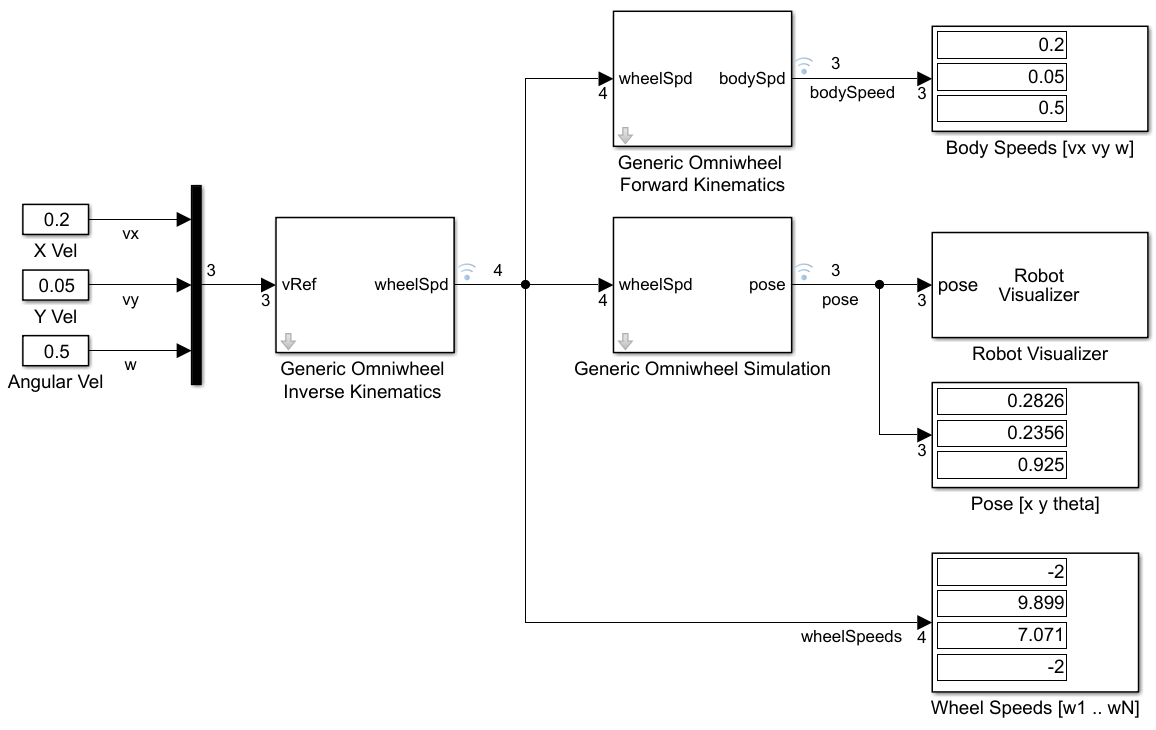

Reference example:

- [Generic omniwheel kinematic simulation](matlab:mrsGenericOmniModel)